# Elaborato equazioni differenziali - circuito

Si consideri il seguente circuito:

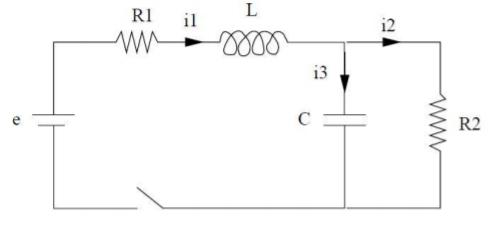

Si vuole valutare la differenza di potenziale `v(t)` ai capi del condensatore C a partire dal tempo` t=0 `in cui è chiuso il circuito. L'equazione che descrive il circuito è:


$$\begin{array}{l}
\mathrm{LCv''}\left(t\right)+\left(R_1 C+\frac{L}{R_2 }\right)\mathrm{v'}\left(t\right)+\left(1+\frac{R_1 }{R_2 }\right)v\left(t\right)=e\\
v\left(t_0 \right)=0,\mathrm{v'}\left(t_0 \right)=0\ldotp 
\end{array}$$


Si vuole trasformare l'equazione nel corrispondente sistema del I ordine, da risolvere utilizzando `ode45` con `RelTol=10e-6` per i valori $L=0\ldotp 1,C={10}^{-3} ,e=5,t\in \left\lbrack 0,0\ldotp 5\right\rbrack \ldotp$

e:

- 
$$R_1 =R_2 =10$$


- 
$$R_1 =1,R_2 =1000$$


Fare il grafico di v(t), v'(t) ed il grafico nel piano delle fasi.

# Soluzione

Assegno i valori alle costanti:

L = 0.1; C = 0.001; e = 5; 

Riscrivo il modello del secondo ordine come un sistema lineare: poniamo $v\left(t\right)=y_1 ,$ $\mathrm{v'}\left(t\right)=y_2$, da cui: 


$$y_1^' =y_2$$



$$y_2^' =\frac{e-\left(1+\frac{R_1 }{R_2 }\right)y_1 -\left(R_1 C+\frac{L}{R_2 }\right)y_2 }{\mathrm{LC}}$$


yd = @(t,y,R1,R2)([y(2);(1/(L*C))*(e-(1+R1/R2)*y(1)-(R1*C+L/R2)*y(2))]);

Definisco il valore iniziale del problema di Cauchy e l'intervallo di tempo da analizzare:

range = [0 0.5];
y0 = [0 0];

Risolvo il sistema utilizzando le funzionalità della ODE suite del Matlab:

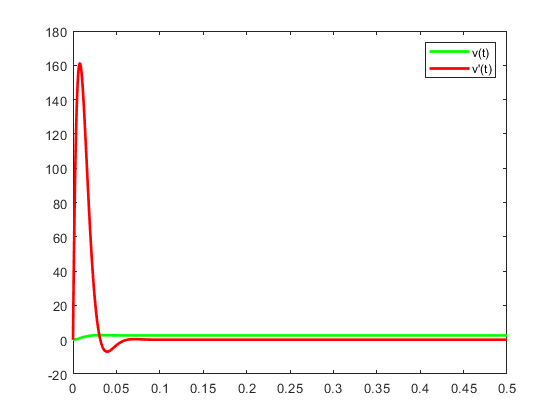

% TEST CON R1=R2=10
opt = odeset('RelTol',1e-6);
R1 = 10; R2 = 10;
[tt,y] = ode45(@(t,y)yd(t,y,R1,R2),range,y0,opt);
plot(tt,y(:,1),'-g',tt,y(:,2),'r','LineWidth',2), legend('v(t)','v''(t)')

Come ci si aspetta, il valore della tensione sul condensatore si stabilizza ad un valore costante che dipende dal generatore iniziale e dalla caduta di tensione sulle due resistenze presenti nel circuito.

La convergenza del fenomeno può essere osservata disegnando il diagramma delle fasi che si ferma nel punto di equilibrio del sistema.

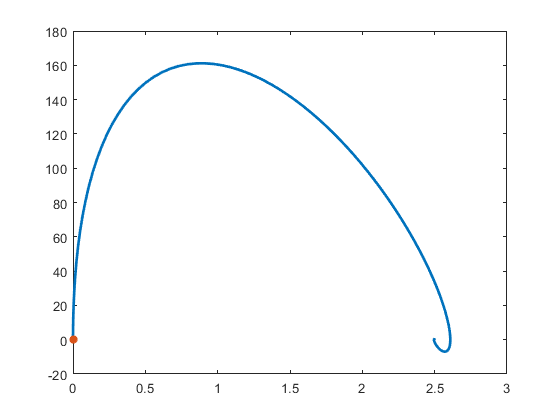

plot(y(:,1),y(:,2),0,0,'*','LineWidth',2)

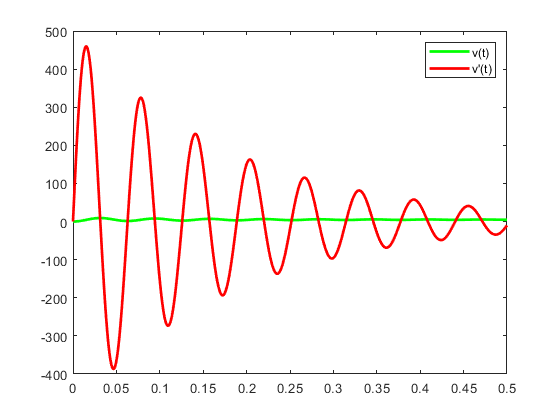

% TEST CON R1=R2=1000
R1 = 1; R2 = 1000;
[tt,y] = ode45(@(t,y)yd(t,y,R1,R2),range,y0,opt);
plot(tt,y(:,1),'-g',tt,y(:,2),'r','LineWidth',2), legend('v(t)','v''(t)')

Come ci si aspetta, quando $R_2$ è molto grande, si comporta come un circuito aperto per cui il circuito si comporta come un circuito RLC serie in regime stazionario: sul transitorio si osserva un fenomeno oscillante dovuto al fatto che lo smorzamento $\frac{1}{\mathrm{LC}}\;>\;1$; a regime l'induttore si comporta come un corto circuito, la caduta di tensione ai capi di $R_1$ è molto piccola e $V_c$ converge al valore del generatore costante $e$. Infine si disegna il diagramma delle fasi: in questo caso la curva è ciclica a causa del fatto che il regime viene raggiunto attraverso continue oscillazioni sempre più piccole intorno al valore del generatore stazionario.

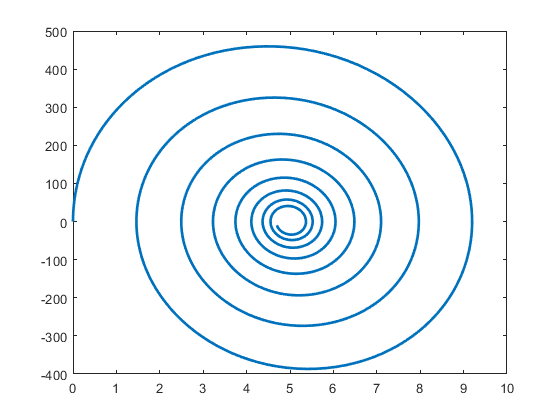

plot(y(:,1),y(:,2),'LineWidth',2)